# Two Species Bifurcation Diagrams

## ODE System

When there are two microbe species present, we get the following (nondimensionalised) ODE system: 

(1)        $
    \frac{\mathrm{d}C_1}{\mathrm{d}t} = C\left(r_1(M)- a_{11}C_1 - a_{12}\gamma C_2\right) 
$

(2)        $
    \frac{\mathrm{d}C_2}{\mathrm{d}t} = C\left(r_2(M)-  a_{21}\gamma C_1 - a_{22}C_2\right) 
$

(3)        $
    \frac{\mathrm{d}M}{\mathrm{d}t} = i - M - pM(C_1 + C_2) 
$    

Where $C_1,C_2$ are the two microbe species and$M$is the metal concentration. Alongside the two growth curves $r_1(M)$ and $r_2(M)$, we have four parameters:

- The community matrix $\mathbf{A}$which dictates the inter and intraspecies competition. As there are no predator-prey dynamics, $a_{ij} > 0 $ for all $i,j$

- A parameter $\gamma$ which varies the relative competition between species

- $i$ which measures the influx of metal to the chemostat

- $p$ which measures the consumption rate of the metal by the microbes

## Equilibria

To describe the equilibria of this system, it is simplest to write our equations in matrix form:


$$\frac{\mathrm{d}\mathbf{C}}{\mathrm{d}t} = \mathbf{C}\odot(\mathbf{r}(M) - \mathbf{A}\mathbf{C})$$



$$\frac{\mathrm{d}M}{\mathrm{d}t} = i - M(1 + \mathbf{p}^T \mathbf{C})$$


where "$$\odot$$" denotes component-wise multiplication. This model has four different types of equilibrium: Total Extinction, Microbe 1 survival, Microbe 2 survival and Coexistence.

### Feasibility Criteria

Total Extinction: $$(0,0,i)$$

- Always feasible

Microbe 1 survival: $$\left(\frac{r_1(M_1)}{a_{11}}, 0, M_1\right)$$ where $$i = M_1\left(1 + \frac{p}{a_{11}} r_1(M_1)\right)$$

-  
$$$M_1 \leq i$$$
 

Microbe 2 survival: $$\left(0, \frac{r_2(M_2)}{a_{22}}, M_2\right)$$ where $$i = M_2\left(1 + \frac{p}{a_{22}}r_2(M_2)\right)$$

- 
$$$M_2 \leq i$$$
 

Coexistence: $$(C^*_1,C^*_2,M^*)$$.

- 
$$$\det(\mathbf{A}) \neq 0$$$


- $$\mathbf{A}^{-1} \mathbf{r}(M^*) .\geq \mathbf{0}$$ (where $$i = M^*\left(1 + \mathbf{p}^T\mathbf{A}^{-1}\mathbf{r}(M^*)\right)$$ and $\mathbf{C^*} = \mathbf{A}^{-1} \mathbf{r}(M^*)$

### Stability Criteria

All of the numbered conditions must occur for the equilibrium to be stable:

Total Extinction: 

- 
$$$\mathbf{r}(i) .\leq \mathbf{0}$$$


Microbe 1 survival: 

- 
$$$a_{11}r_2(M_1) - a_{21}r_1(M_1) < 0$$$
 

- 
$$$r'_1(M_1) > -\frac{i a_{11}}{p M_1 ^2} \Longleftrightarrow \frac{i a_{11}}{M_1} + p M_1 r'_1(M_1) > 0$$$


Microbe 2 survival:  

- 
$$$a_{22}r_1(M_2) - a_{12}r_2(M_2) < 0$ $$


- 
$$$r'_2(M_2) > -\frac{i a_{22}}{p M_2 ^2} \Longleftrightarrow \frac{i a_{22}}{M_2} + p M_2 r'_2(M_2) > 0$$$


Coexistence: 

    If we write our characteristic polynomial as $$\lambda^3 + c_2\lambda^2 + c_1\lambda + c_0 = 0$$, we can use the **Routh-Hurwitz conditions** to get stability criteria solely in terms of our coefficients $$c_i$$.

- $$c_2 = a_{11}C_1^* + a_{22}C_2^* + \frac{i}{M^*} > 0$$ (where feasible, this condition is always met)

- 
$$$c_1 = \det(\mathbf{A})C^*_1C^*_2 + C^*_1\left(\frac{i a_{11}}{M^*} + p M^* r'_1(M^*)\right) + C^*_2\left(\frac{i a_{22}}{M^*} + p M^* r'_2(M^*)\right) > 0$$$
 

- 
$$$c_0 = \det(\mathbf{A})C_1^*C_2^*\left(\frac{i}{M^*} + M^*\mathbf{p}^T\mathbf{A}^{-1}\mathbf{r'}(M^*)\right) > 0$$$


- 
$$$c_2 c_1 > c_0$$$


These stability criteria are too complex to explore directly. However, an important note is that all of our equilibria and stability conditions can be written solely in terms of $M$. Therefore, all of our conditions can be reduced to scalar equations which can then be solved numerically very quickly. To utilise this, we have created a program to generate two-parameter bifurcation diagrams to then infer information about the system.

The two parameters displayed on the diagram are $i$, the metal influx rate and $\gamma$, the competition strength. For a particular pair of parameters ($i,\gamma$), we calculate the number and type (extinction or survival) of each **stable** equilibria. This point is then assigned a colour according to which and how many equilbria are stable. For simplicity, we take $a_{11} = a_{22} = 0$ and $a_{12}=a_{21} = \gamma$

## Parameters and Growth Functions

First, the growth functions $r_1(M)$ and $r_2(M)$ are set, along with the parameter $p$:

r1_input = "sech(5-M)-0.1";
isValidFunction = true;
try
    r1 = str2func(strcat('@(M)',r1_input)); 
    r1(1);  
catch
    isValidFunction = false;
end

if isValidFunction
    disp('Valid input');
else
    disp('The input is NOT a valid MATLAB function.');
end

Valid input


r2_input = "sech(7-M)-0.1";
isValidFunction = true;
try
    r2 = str2func(strcat('@(M)',r2_input)); 
    r2(1);    
catch
    isValidFunction = false;
end

if isValidFunction
    disp('Valid input');
else
    disp('The input is NOT a valid MATLAB function.');
end

Valid input


p =0.15;

Next, the display values are chosen. These are the maximum values of $i$ and $\gamma$, and the resolution (number of grid points).

i_max =12;
gamma_max =2;
num_points = 250;

## Diagram

- Red - Microbe 1 Survival

- Blue - Microbe 2 Survival

- Green - Coexistence

- Pink - Competitive Exclusion (both partial extinction states are stable)

- Grey - All non-extinction states stable

- White - Extinction

- Black - Limit Cycles (about an unstable coexistence equilibrium)

Bistability is represented by mixing the relevant colours together e.g. Cyan is Microbe 2 Survival and Coexistence bistability

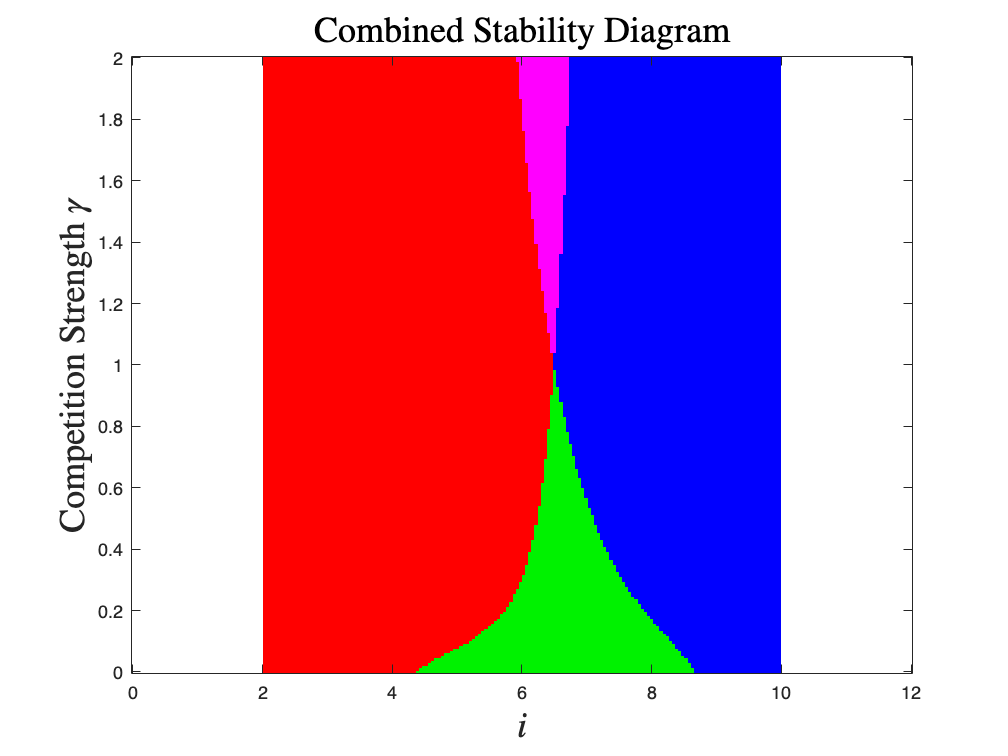

 
syms x
r1_sym = r1(x);
r2_sym = r2(x);

r1deriv_sym = diff(r1_sym, x);
r2deriv_sym = diff(r2_sym, x);

r1deriv = matlabFunction(r1deriv_sym);
r2deriv = matlabFunction(r2deriv_sym);

% Root finder
function solutions = FindRoots(f,lower_bound,upper_bound) 
    min_resolution = 1e-2;
    num_points = ceil((upper_bound-lower_bound)/min_resolution);    
    x = linspace(lower_bound,upper_bound,num_points);
    fvals = f(x);
    sign_check = diff(sign(fvals)) ~= 0;
    I = find(sign_check);
    solutions = [];
    for i = I
        try
            [X,~,EXITFLAG] = fzero(f,[x(i),x(i+1)]);
            solutions = [solutions,X];
        catch
            disp('Warning: fzero failed; printing EXITFLAG in next line')
            disp(EXITFLAG)
        end
    end
end

% Preallocation
A = linspace(0,gamma_max,num_points);
I = linspace(0,i_max,num_points);
combined_colours = zeros(num_points);

% Main Loop
parfor k = 1:num_points
    i = I(k);

    %Extinction equilibria (Always feasible)
    ex_flag = 0;
    if r1(i) < 0 && r2(i) < 0  % Stability 
        ex_flag = 1;  
    end

    % M1,M2 survival equilibria 
    G1 = @(M) p.*M.*r1(M) - (i-M)
    root_m1 = FindRoots(G1,0,i)

    G2 = @(M) p.*M.*r2(M) - (i-M);
    root_m2 = FindRoots(G2,0,i)

    for j = 1:num_points
        a = A(j);

        % M1 survival stability - Red
        m1_flag = 0;
        for root = root_m1 % Feasibility given by choice of bounds
            stab1 = p*root*r2(root) - a*(i-root); 
            stab2 = i + p*root^2*r1deriv(root);
            if stab1 <= 0 && stab2 > 0 % Stability
                m1_flag = 1;
            end
        end

        % M2 survival stability - Blue
        m2_flag = 0;     
        for root = root_m2 % Feasibility given by choice of bounds
            stab1 = p*root*r1(root) - a*(i-root); 
            stab2 = i + p*root^2*r2deriv(root);
            if stab1 <= 0 && stab2 > 0 % Stability
                m2_flag = 1;
            end
        end

        %Coexistence equilibria - Green 

        G = @(M) p.*M.*((1-a).*r1(M) + (1-a).*r2(M)) - (1 - a^2).*(i-M);

        co_flag = 0;
        for root = FindRoots(G,0,i)
            C_1 = (r1(root)-(a.*r2(root)))./(1-a^2);
            C_2 = (r2(root)-(a.*r1(root)))./(1-a^2);
            C = [C_1;C_2];
            if all(C > 0) % Feasibility

                c_2 = root*(C_1+C_2) + i;
                c_1 = (1-a^2)*root*C_1*C_2 + ...
                      C_1*(i + p*r1deriv(root)*root^2) + ...
                      C_2*(i + p*r2deriv(root)*root^2);
                c_0 = (1-a^2)*C_1*C_2*(i + p*(1+a)*(r1deriv(root)+r2deriv(root))*root^2);
                condition = c_2*c_1 - root*c_0;

                coefficients = [c_0,c_1,c_2,condition]
                if all(coefficients > 0) % Stability 
                    co_flag = 1;
                end
            end
        end

        % Colour scheme 

        flag_val = 8*co_flag + 4*m2_flag + 2*m1_flag + ex_flag; 

        switch flag_val
            case 1 % White - Extinction only
                combined_colours(j,k) = 0
            case 2 % Red - M1 only
                combined_colours(j,k) = 2
            case 3 % Light Red - M1 + Extinction
                combined_colours(j,k) = 3
            case 4 % Blue - M2 only
                combined_colours(j,k) = 4
            case 5 % Light Blue - M2 + Extinction
                combined_colours(j,k) = 5
            case 6 % Magenta - M1 + M2
                combined_colours(j,k) = 8
            case 7 % Light Magenta - M1 + M2 + Extinction
                combined_colours(j,k) = 11
            case 8 % Green - Coexistence
                combined_colours(j,k) = 6  
            case 9 % Light Green - Coexistence + Extinction
                combined_colours(j,k) = 7
            case 10 % Yellow - Coexistence + M1
                combined_colours(j,k) = 9
            case 11 % Light Yellow - Coexistence + M1 + Extinction
                combined_colours(j,k) = 12
            case 12 % Cyan - Coexistence + M2
                combined_colours(j,k) = 10
            case 13 % Light Cyan - Coexistence + M2 + Extinction
                combined_colours(j,k) = 13
            case 14 % Dark Grey - Coexistence + M1 + M2
                combined_colours(j,k) = 14
            case 15 % Grey - All
                combined_colours(j,k) = 15
            otherwise % Black - None/Error
                combined_colours(j,k) = 1
        end
    end
end
% Color Map created with RGB Triplets
customColorMap = [
    1, 1, 1;          % 0 = White
    0, 0, 0;          % 1 = Black  
    1, 0, 0;          % 2 = Red
    1, 0.5, 0.5;      % 3 = Light Red
    0, 0, 1;          % 4 = Blue
    0.5, 0.5, 1;      % 5 = Light Blue
    0, 0.95, 0;       % 6 = Green
    0.4, 1, 0.4;      % 7 = Light Green
    1, 0, 1;          % 8 = Magenta
    1, 1, 0;          % 9 = Yellow
    0, 1, 1;          % 10 = Cyan
    1, 0.5, 1;        % 11 = Light Magenta
    1, 1, 0.5;        % 12 = Light Yellow
    0.5, 1, 1;        % 13 = Light Cyan
    0.5, 0.5, 0.5;    % 14 = Dark Grey
    0.75, 0.75, 0.75; % 15 = Grey
    ];

% Plot using imagesc
yspace = linspace(0,gamma_max,num_points);
xspace = linspace(0,i_max,num_points);

figure;
clf;
colormap(customColorMap)
imagesc(xspace,yspace,combined_colours)
set(gca, 'CLim', [0 length(customColorMap) - 1]);
set(groot, 'defaultFigureVisible', 'on');
axis xy
title("Combined Stability Diagram",'Interpreter','latex', 'FontSize', 20)
xlabel('$i$','Interpreter','latex', 'FontSize', 20)
ylabel('Competition Strength $\gamma$','Interpreter','latex', 'FontSize', 20)